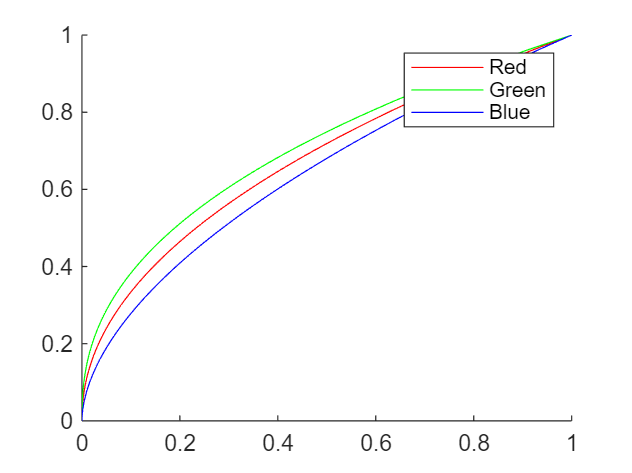

%1.1
clear
load("TRC_display.mat")
colorRange=0:0.01:1;
hold on
plot(TRCr,colorRange,"r")
plot(TRCg,colorRange,"g")
plot(TRCb,colorRange,"b")
legend("Red","Green","Blue")
hold off

Answer: Since the gamma curve is inverted, the image will have an inverted color effect to it, the colors will be approximately correct whilst inverted.

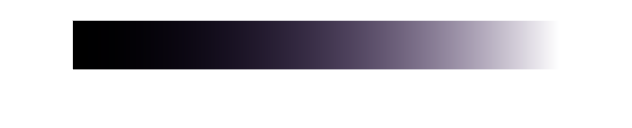

%1.2
load("Ramp_display.mat")
load("Ramp_linear.mat")
imshow(Ramp_display)

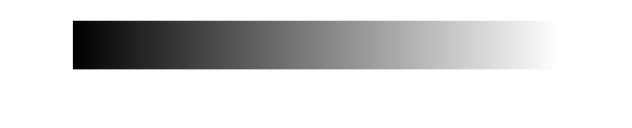

imshow(Ramp_linear)

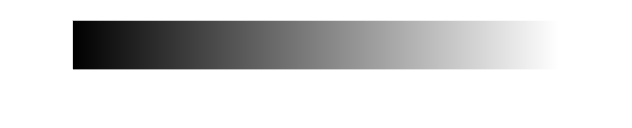


yr=interp1(TRCr,colorRange,Ramp_display(:,:,1),'pchip');
yg=interp1(TRCg,colorRange,Ramp_display(:,:,2),'pchip');
yb=interp1(TRCb,colorRange,Ramp_display(:,:,3),'pchip');

Ramp_display_Corrected=cat(3,yr,yb,yg);
imshow(Ramp_display_Corrected);

Ramp is now neutral. It's not identical but the color is corrected

%1.3
yr=2,1;

yr = 2

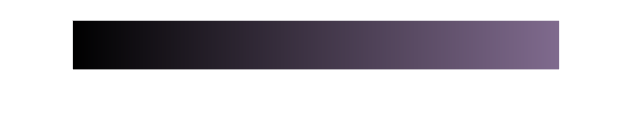

yg=2.4;
yb=1.8;
RampCorGamma=cat(3,Ramp_display_Corrected(:,:,1).^1/yr, Ramp_display_Corrected(:,:,2).^1/yg,Ramp_display_Corrected(:,:,3).^1/yb);
imshow(RampCorGamma)

Ramp is now seemingly linear, going from black to color.

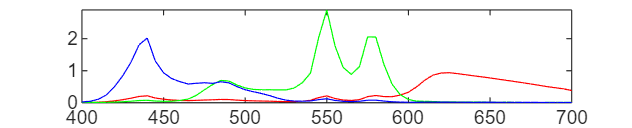

%2.1
clear
load("DLP.mat")
ramp=400:5:700;

plot(ramp,DLP(:,1),"r")
hold on
plot(ramp,DLP(:,2),"g")
plot(ramp,DLP(:,3),"b")
hold off

Projector has bad representation of red, but heavy rep for blue and ever heavier for green.

%2.2
load("RGB_raw.mat")
%Srgb=DLP*RGB_raw;
Srgb=RGB_raw(1,8)*DLP(:,1)+ RGB_raw(2,8)*DLP(:,2)+ RGB_raw(3,8)*DLP(:,3);
for i=1:20
    Srgb(i)=RGB_raw(1,i)*DLP(:,1)+RGB_raw(2,i)*DLP(:,2)+ RGB_raw(3,i)*DLP(:,3);
end